Cluster participants into strategies using HBI responsibility, then compare their ratings (av_pdiv: average rating to the knowledge diversity combination; av_nodiv: average rating to the same knowledge combination) , and time across strategy clusters.

clear; clc;

projectDir = '/Users/foxxis/Desktop/HBI/exp2';

cd(projectDir);
addpath(projectDir);

addpath(fullfile(projectDir, 'src'));
addpath(fullfile(projectDir, 'src', 'models'));
addpath(fullfile(projectDir, 'src', 'plotting'));
addpath(fullfile(projectDir, 'src', 'r2_assignment'));

## Load summary metrics

% Load the dataset and the hbi result
data_file = '/Users/foxxis/Documents/social induction/experiment data/exp2/final_data.csv';
hbi_file  = fullfile(projectDir, 'results', 'fitting', 'hbi_compare.mat');

% read the dataset
Sum = readtable(data_file);
needVars = {'av_pdiv','av_nodiv','t','div_t','nodiv_t'};
Sum = Sum(:, needVars);
Sum.av_pdiv = Sum.av_pdiv * 2; % turn it into 0-100 scale
Sum.av_nodiv = Sum.av_nodiv * 2;

% read the hbi result
S = load(hbi_file);
cbm = S.cbm;
resp = cbm.output.responsibility; 

## Informativness Ratings

T = Sum(:, {'av_pdiv','av_nodiv'});

% descriptive statistics
desc = table(["pdiv";"nodiv"], ...
    [mean(T.av_pdiv,'omitnan'); mean(T.av_nodiv,'omitnan')], ...
    [std(T.av_pdiv,'omitnan'); std(T.av_nodiv,'omitnan')], ...
    'VariableNames', {'Condition','Mean','SD'});
disp(desc)

    Condition     Mean       SD  
    _________    ______    ______

     "pdiv"      60.471    19.382
     "nodiv"     39.529    19.382




within = table(["pdiv"; "nodiv"], 'VariableNames', {'Condition'});

% repeated-measures anova
rm = fitrm(T, 'av_pdiv-av_nodiv ~ 1', 'WithinDesign', within);
ranovatbl = ranova(rm, 'WithinModel', 'Condition');
disp(ranovatbl)

                               SumSq       DF      MeanSq          F           pValue       pValueGG      pValueHF      pValueLB 
                             __________    __    __________    __________    __________    __________    __________    __________

    (Intercept)                4.35e+05     1      4.35e+05    2.3156e+34             0             0             0             0
    Error                    1.6156e-27    86    1.8786e-29                                                                      
    (Intercept):Condition         19079     1         19079        25.394    2.5552e-06    2.5552e-06    2.5552e-06    2.5552e-06
    Error(Conditio


SS_condition = ranovatbl.SumSq("(Intercept):Condition");
SS_error = ranovatbl.SumSq("Error(Condition)");
eta_p2 = SS_condition / (SS_condition + SS_error);
disp("eta_p2=" + string(eta_p2))

eta_p2=0.22797


## Cluster participants into strategies

% Names of the models in the same order as cbm.output.responsibility
% Mentalizing, VT, DW, KW, and Baseline
strategyNames = {'Mentalizing','VT','DW','KW','Baseline'};
nModels_expected = numel(strategyNames);
[respMax, stratIdx] = max(resp, [], 2);

% Force column vectors
respMax  = respMax(:);
stratIdx = stratIdx(:);

% strategy categorical
strategy = categorical(strategyNames(stratIdx), strategyNames);
strategy = strategy(:);

% strategyU (with Uncertain)
% The manuscript set confThr = 0.6
confThr = 0.6;
strategyU = categorical(strategyNames(stratIdx), [strategyNames, {'Uncertain'}]);
strategyU(respMax < confThr) = categorical({'Uncertain'});
strategyU = strategyU(:);

StratTbl = table(strategy, strategyU, respMax, stratIdx, ...
    'VariableNames', {'strategy','strategyU','respMax','stratIdx'});

% Convert responsibility matrix into a table with meaningful column names
RespTbl = array2table(resp, 'VariableNames', ...
    {'r_mentalizing','r_vt','r_dw','r_kw','r_baseline'});

% Combine the participants' data, strategy categorization, and
% responsiblity matrix into the same dataframe
A = [Sum, StratTbl, RespTbl];


% exclude Uncertain
A = A(A.strategyU ~= categorical({'Uncertain'}), :);


% Drop empty categories to avoid "jumping indices" in old functions
A.strategyU = removecats(A.strategyU);

## ANOVA

pA = 0.9340

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[    2.6036]}    {[ 1]}    {[  2.6036]}    {[  0.0069]}    {[  0.9340]}
    {'Error' }    {[2.5640e+04]}    {[68]}    {[377.0659]}    {0×0 double}    {0×0 double}
    {'Total' }    {[2.5643e+04]}    {[69]}    {0×0 double}    {0×0 double}    {0×0 double}


stats = struct with fields:
    gnames: {2×1 cell}
         n: [56 14]
    source: 'anova1'
     means: [60.5893 61.0714]
        df: 68
         s: 19.4182


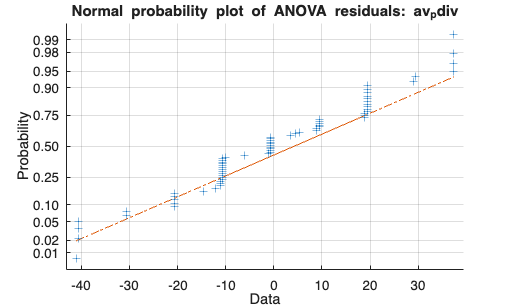

pA = 0.9340

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[    2.6036]}    {[ 1]}    {[  2.6036]}    {[  0.0069]}    {[  0.9340]}
    {'Error' }    {[2.5640e+04]}    {[68]}    {[377.0659]}    {0×0 double}    {0×0 double}
    {'Total' }    {[2.5643e+04]}    {[69]}    {0×0 double}    {0×0 double}    {0×0 double}


stats = struct with fields:
    gnames: {2×1 cell}
         n: [56 14]
    source: 'anova1'
     means: [39.4107 38.9286]
        df: 68
         s: 19.4182


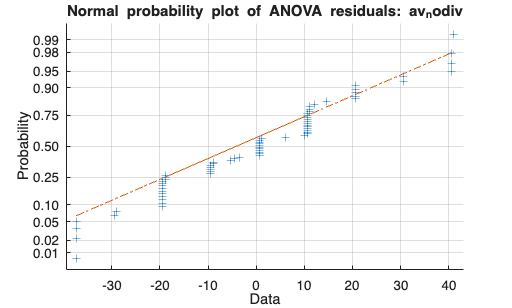

pA = 0.3417

tbl = 4×6 cell array
    {'Source'}    {'SS'     }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[ 0.5546]}    {[ 1]}    {[  0.5546]}    {[  0.9170]}    {[  0.3417]}
    {'Error' }    {[41.1253]}    {[68]}    {[  0.6048]}    {0×0 double}    {0×0 double}
    {'Total' }    {[41.6799]}    {[69]}    {0×0 double}    {0×0 double}    {0×0 double}


stats = struct with fields:
    gnames: {2×1 cell}
         n: [56 14]
    source: 'anova1'
     means: [4.5778 4.8003]
        df: 68
         s: 0.7777


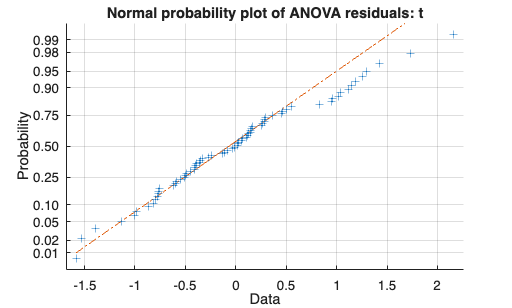

pA = 0.7292

tbl = 4×6 cell array
    {'Source'}    {'SS'     }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[ 0.0932]}    {[ 1]}    {[  0.0932]}    {[  0.1209]}    {[  0.7292]}
    {'Error' }    {[52.4586]}    {[68]}    {[  0.7714]}    {0×0 double}    {0×0 double}
    {'Total' }    {[52.5518]}    {[69]}    {0×0 double}    {0×0 double}    {0×0 double}


stats = struct with fields:
    gnames: {2×1 cell}
         n: [56 14]
    source: 'anova1'
     means: [3.9488 4.0400]
        df: 68
         s: 0.8783


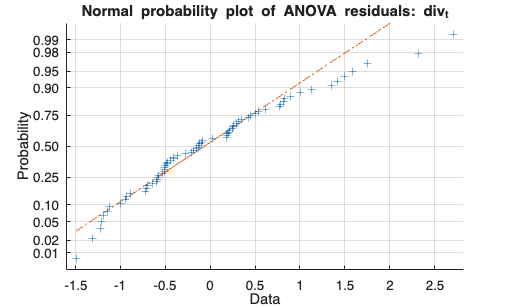

pA = 0.1205

tbl = 4×6 cell array
    {'Source'}    {'SS'     }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[ 1.4261]}    {[ 1]}    {[  1.4261]}    {[  2.4722]}    {[  0.1205]}
    {'Error' }    {[39.2271]}    {[68]}    {[  0.5769]}    {0×0 double}    {0×0 double}
    {'Total' }    {[40.6532]}    {[69]}    {0×0 double}    {0×0 double}    {0×0 double}


stats = struct with fields:
    gnames: {2×1 cell}
         n: [56 14]
    source: 'anova1'
     means: [3.6790 4.0359]
        df: 68
         s: 0.7595


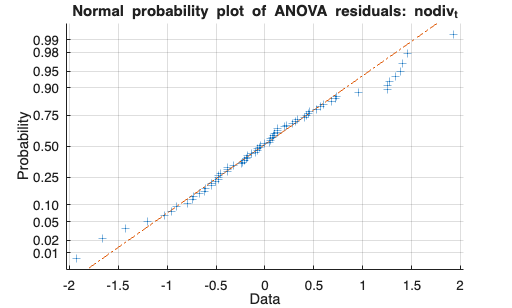

metrics = {'av_pdiv','av_nodiv','t','div_t','nodiv_t'};
logMetrics = {'t','div_t','nodiv_t'}; % use log transform for time
% meaning of each metric
% av_pdiv: rating of informativeness for pairs with knowledge diversity
% av_nodiv: rating of informativeness for pairs with no knowledge diversity
% t: time for completing the trials
% div_t: time for completing the trials interacting with informants with
% knowledge diversity
% nodiv_t: time for completing the trials interacting with informants with
% no knowledge diversity

minGroupN = 5;  % if a strategy group includes less than 5 participants, exclude that group from analysis

% prepare the output
R = cell(0,6);               

% Use log transform for time metrics


for k = 1:numel(metrics)
    % For each metric, organize participant-level values and their assigned
    % category labels for comparison
    yName = metrics{k};
    y = A.(yName);
    g = A.strategyU;

    if ismember(yName, logMetrics)
      y = log(y);
      yNameOut = [yName '_log'];
    else
      yNameOut = yName;
    end

    % Remove groups with fewer than minGroupN participants
    [gID, ~] = findgroups(g);
    grpN = accumarray(gID, 1);
    keepGroup = grpN >= minGroupN;
    keepObs = keepGroup(gID);

    % Recompute groups after excluding small groups
    y = y(keepObs);
    g = g(keepObs);
    [gID, gNames] = findgroups(g);

    K = numel(gNames);
    % If there are less than 2 categories, skip the anova analysis
    if K < 2
        warning('%s: <2 groups; skipped.', yName); 
        continue;
    end

    % One-way ANOVA
    [pA, tbl, stats] = anova1(y, gID,'off')
    eta2 = tbl{2,2} / tbl{4,2};
    Fstat = tbl{2,5};
    
    % Normality check using residuals
    groupMean = splitapply(@mean, y, gID);
    residuals = y - groupMean(gID);
    figure;
    normplot(residuals);
    title(sprintf('Normal probability plot of ANOVA residuals: %s', yName));

    R(end+1,:) = {yName, numel(y), K, Fstat, pA, eta2}; 
end


Results = cell2table(R, 'VariableNames', {'metric','N','kGroups','F', 'p_anova','eta2'});

disp('===ANOVA Summary===');

===ANOVA Summary===


disp(Results);

       metric       N     kGroups        F        p_anova       eta2   
    ____________    __    _______    _________    _______    __________

    {'av_pdiv' }    70       2       0.0069048    0.93402    0.00010153
    {'av_nodiv'}    70       2       0.0069048    0.93402    0.00010153
    {'t'       }    70       2         0.91701    0.34165      0.013306
    {'div_t'   }    70       2         0.12086    0.72918     0.0017742
    {'nodiv_t' }    70       2          2.4722    0.12052       0.03508



needVars = {'av_pdiv','av_nodiv','t','div_t','nodiv_t'};
group_descriptives(A, needVars);

=== Group descriptives (mean, SEM) ===
     strategyU      N     mean_av_pdiv    sd_av_pdiv    sem_av_pdiv    n_av_pdiv    mean_av_nodiv    sd_av_nodiv    sem_av_nodiv    n_av_nodiv    mean_t     sd_t     sem_t     n_t    mean_div_t    sd_div_t    sem_div_t    n_div_t    mean_nodiv_t    sd_nodiv_t    sem_nodiv_t    n_nodiv_t
    ____________    __    ____________    __________    ___________    _________    _____________    ___________    ____________    ______

## Robustness Check using different confThr

% strategyU (with Uncertain)
confThrList = [0,0.2,0.4,0.8];
% Store results across all thresholds
R = cell(0,8);

for c = 1:numel(confThrList)
    confThr = confThrList(c);
    strategyU = categorical(strategyNames(stratIdx), [strategyNames, {'Uncertain'}]);
    strategyU(respMax < confThr) = categorical({'Uncertain'});
    strategyU = strategyU(:);
    
    StratTbl = table(strategy, strategyU, respMax, stratIdx, ...
        'VariableNames', {'strategy','strategyU','respMax','stratIdx'});
    
    % Convert responsibility matrix into a table with meaningful column names
    RespTbl = array2table(resp, 'VariableNames', ...
        {'r_mentalizing','r_vt','r_dw','r_kw','r_baseline'});
    
    % Combine the participants' data, strategy categorization, and
    % responsiblity matrix into the same dataframe
    A = [Sum, StratTbl, RespTbl];
    
    
    % exclude Uncertain
    A = A(A.strategyU ~= categorical({'Uncertain'}), :);
    
    
    % Drop empty categories to avoid "jumping indices" in old functions
    A.strategyU = removecats(A.strategyU);
    
    metrics =  {'av_pdiv','av_nodiv','t','div_t','nodiv_t'};
    
    logMetrics = {'t','div_t','nodiv_t'}; % use log transform for time
    % meaning of each metric
    % av_pdiv: rating of informativeness for pairs with knowledge diversity
    % av_nodiv: rating of informativeness for pairs with no knowledge diversity
    % t: time for completing the trials
    % div_t: time for completing the trials interacting with informants with
    % knowledge diversity
    % nodiv_t: time for completing the trials interacting with informants with
    % no knowledge diversity
    
    minGroupN = 5;  % if a strategy group includes less than 5 participants, exclude that group from analysis
    

    % Use log transform for time metrics
    
    
    for k = 1:numel(metrics)
        % For each metric, organize participant-level values and their assigned
        % category labels for comparison
        yName = metrics{k};
        y = A.(yName);
        g = A.strategyU;
    
        if ismember(yName, logMetrics)
          y = log(y);
          yNameOut = [yName '_log'];
        else
          yNameOut = yName;
        end
    
        % Remove groups with fewer than minGroupN participants
        [gID, ~] = findgroups(g);
        grpN = accumarray(gID, 1);
        keepGroup = grpN >= minGroupN;
        keepObs = keepGroup(gID);
    
        % Recompute groups after excluding small groups
        y = y(keepObs);
        g = g(keepObs);
        [gID, gNames] = findgroups(g);
    
        K = numel(gNames);
        % If there are less than 2 categories, skip the anova analysis
        if K < 2
            warning('%s: <2 groups; skipped.', yName); 
            continue;
        end
    
        % One-way ANOVA
        [pA, tbl, stats] = anova1(y, gID,'off');
        eta2 = tbl{2,2} / tbl{4,2};
        Fstat = tbl{2,5};
        
        includedGroups = strjoin(string(gNames), ', ');

        R(end+1,:) = {confThr, yNameOut, numel(y), K, ...
                     includedGroups, Fstat, pA, eta2};
    end
    
    
    needVars = {'av_pdiv','av_nodiv','t','div_t','nodiv_t'
        };
    fprintf('\n=== Group descriptives: confThr = %.2f ===\n', confThr);
    group_descriptives(A, needVars);
end


=== Group descriptives: confThr = 0.00 ===


=== Group descriptives (mean, SEM) ===
       strategyU       N     mean_av_pdiv    sd_av_pdiv    sem_av_pdiv    n_av_pdiv    mean_av_nodiv    sd_av_nodiv    sem_av_nodiv    n_av_nodiv    mean_t     sd_t     sem_t     n_t    mean_div_t    sd_div_t    sem_div_t    n_div_t    mean_nodiv_t    sd_nodiv_t    sem_nodiv_t    n_nodiv_t
    _______________    __    ____________    __________    ___________    _________    _____________    ___________    ____________    


=== Group descriptives: confThr = 0.20 ===


=== Group descriptives (mean, SEM) ===
       strategyU       N     mean_av_pdiv    sd_av_pdiv    sem_av_pdiv    n_av_pdiv    mean_av_nodiv    sd_av_nodiv    sem_av_nodiv    n_av_nodiv    mean_t     sd_t     sem_t     n_t    mean_div_t    sd_div_t    sem_div_t    n_div_t    mean_nodiv_t    sd_nodiv_t    sem_nodiv_t    n_nodiv_t
    _______________    __    ____________    __________    ___________    _________    _____________    ___________    ____________    


=== Group descriptives: confThr = 0.40 ===


=== Group descriptives (mean, SEM) ===
       strategyU       N     mean_av_pdiv    sd_av_pdiv    sem_av_pdiv    n_av_pdiv    mean_av_nodiv    sd_av_nodiv    sem_av_nodiv    n_av_nodiv    mean_t     sd_t     sem_t     n_t    mean_div_t    sd_div_t    sem_div_t    n_div_t    mean_nodiv_t    sd_nodiv_t    sem_nodiv_t    n_nodiv_t
    _______________    __    ____________    __________    ___________    _________    _____________    ___________    ____________    


=== Group descriptives: confThr = 0.80 ===


=== Group descriptives (mean, SEM) ===
     strategyU      N     mean_av_pdiv    sd_av_pdiv    sem_av_pdiv    n_av_pdiv    mean_av_nodiv    sd_av_nodiv    sem_av_nodiv    n_av_nodiv    mean_t     sd_t     sem_t     n_t    mean_div_t    sd_div_t    sem_div_t    n_div_t    mean_nodiv_t    sd_nodiv_t    sem_nodiv_t    n_nodiv_t
    ____________    __    ____________    __________    ___________    _________    _____________    ___________    ____________    ______


% Combine results from all thresholds
RobustResults = cell2table(R, 'VariableNames', ...
    {'confThr','metric','N','kGroups','includedGroups', ...
     'F','p_anova','eta2'});

% Place different thresholds for the same metric together
RobustResults = sortrows(RobustResults, {'metric','confThr'});

disp('=== ANOVA robustness across confidence thresholds ===');

=== ANOVA robustness across confidence thresholds ===


disp(RobustResults);

    confThr        metric         N     kGroups          includedGroups              F        p_anova        eta2   
    _______    _______________    __    _______    ___________________________    ________    ________    __________

        0      {'av_nodiv'   }    86       3       "Mentalizing, KW, Baseline"     0.12662     0.88124     0.0030417
      0.2      {'av_nodiv'   }    86       3       "Mentalizing, KW, Baseline"     0.12662     0.88124     0.0030417
      0.4      {'av_nodiv'   }    85       3       "Mentalizing, KW, Baseline"      0.1115     0.89463     0.0027122
      0.8      {'av_nodiv'   }    51       2       "KW, Baseline"                  0.75992     0.38761      0.015272
        0      {'av_pdiv'

helper function

function group_descriptives(A, needVars)

% Exclude strategy groups with fewer than 5 participants
g = A.strategyU;
groupNames = categories(g);
groupN = countcats(g);
keepGroups = groupNames(groupN >= 5);

A = A(ismember(g, keepGroups), :);
A.strategyU = removecats(A.strategyU);

% Recompute group indices after filtering
g = A.strategyU;
[Gid, gLabels] = grp2idx(g);

Desc = table(gLabels(:), accumarray(Gid, 1), 'VariableNames', {'strategyU','N'});

for i = 1:numel(needVars)
    yName = needVars{i};
    y = A.(yName);

    m = splitapply(@mean, y, Gid);
    sd = splitapply(@std, y, Gid);
    n = splitapply(@numel, y, Gid);
    sem = sd ./ sqrt(n);

    Desc.(['mean_' yName]) = m;
    Desc.(['sd_' yName]) = sd;
    Desc.(['sem_' yName]) = sem;
    Desc.(['n_' yName]) = n;
end

disp('=== Group descriptives (mean, SEM) ===');
disp(Desc);

end